# Combining Learners, Decision Trees and Random Forests

## Combining Learners

If the individual machine learning models we have studied in the course are not complicated enough for you, how about combining multiple learners together?!  It turns out that this isn't as crazy as it might first seem.  In recent years techniques for combining learners, aka committee or ensemble methods have generated a huge amount of interest and have produced some of the best performance results in a wide range of practical applications.

Unfortunately we don't have time to cover some of the ideas and models in this area, but we will take a look at the two most common general techniques: bagging and boosting.

## Combining Outputs

Most commonly done as a majority vote for classifiers or an average for regression models:

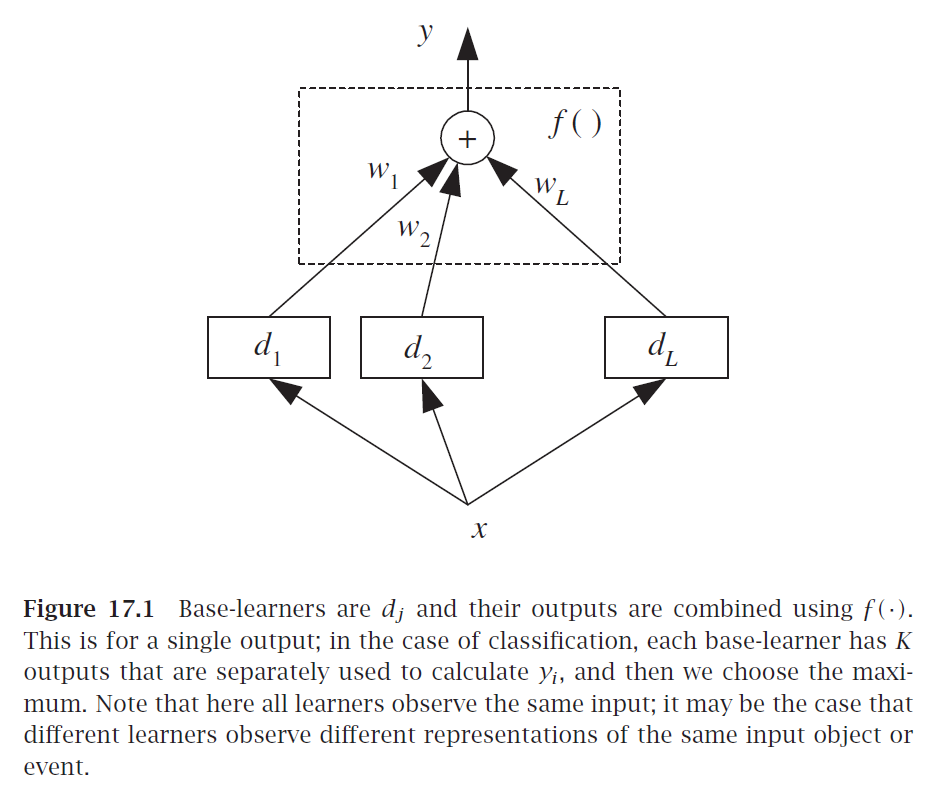

## Bagging

Use a bootstrapping to generate $L$ training sets and train one base learner with each.

Incredibly simple!

Unstable algorithms profit from bagging (why?)

## Boosting

Boosting algorithms actively try and generate a committee where the base leaners try and complement each other to get better performance.  While a bagged ensemble can be constructed in parallel, in boosting learners are added sequentially, each new member focussing on the errors made by previous members.

### Adaboost.M1

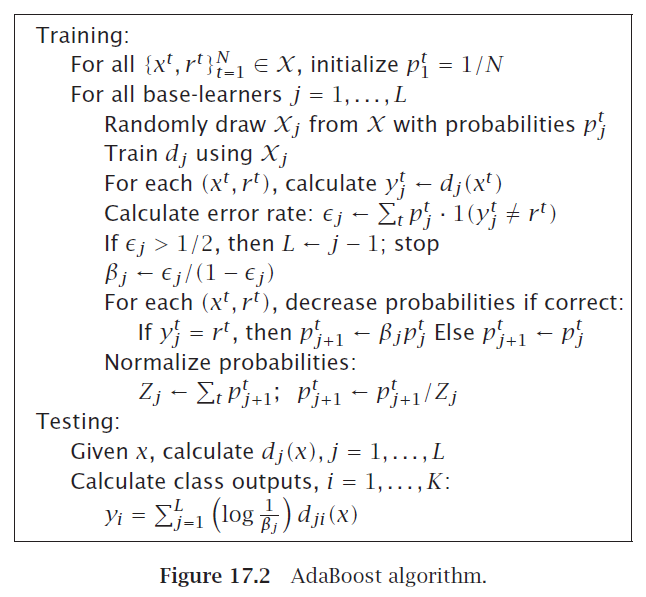

It can be shown/argued that AdaBoost tends to increase the margin during learning (recall SVMs).

## Decision Trees

Decision trees are a very popular supervised learning model.  We won't go into them in great detail (more may be in the INFS Data Mining course).

Perhaps their main advantage is their **transparency** and **interpretability**.

Let's focus on (binary, univariate) decision trees for classification.

%% View Decision Tree
% This example shows how to view a classification or regression tree.
% There are two ways to view a tree: |view(tree)| returns a text
% description and |view(tree,'mode','graph')| returns a graphic description
% of the tree.
%%
% Create and view a classification tree.
load fisheriris % load the sample data
ctree = fitctree(meas,species); % create classification tree
view(ctree) % text description


Decision tree for classification
1  if x3<2.45 then node 2 elseif x3>=2.45 then node 3 else setosa
2  class = setosa
3  if x4<1.75 then node 4 elseif x4>=1.75 then node 5 else versicolor
4  if x3<4.95 then node 6 elseif x3>=4.95 then node 7 else versicolor
5  class = virginica
6  if x4<1.65 then node 8 elseif x4>=1.65 then node 9 else versicolor
7  class = virginica
8  class = versicolor
9  class = virginica



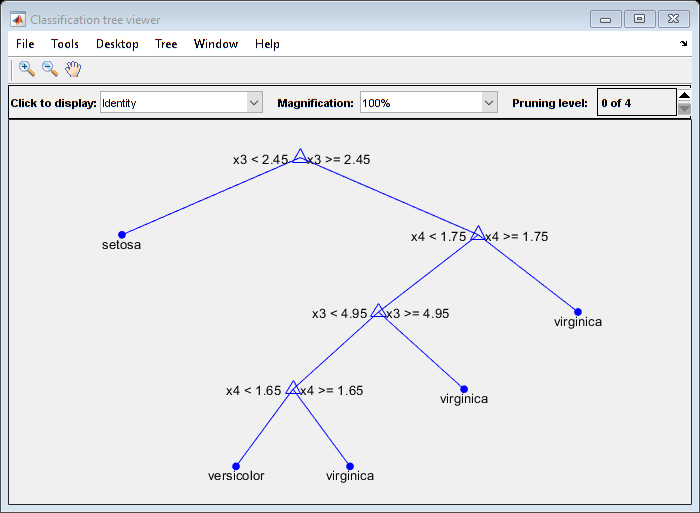

%%
view(ctree,'mode','graph') % graphic description

%%
% Now, create and view a regression tree.
load carsmall % load the sample data, contains Horsepower, Weight, MPG
X = [Horsepower Weight];
rtree = fitrtree(X,MPG,'MinParent',30); % create classification tree
view(rtree) % text description


Decision tree for regression
1  if x2<3085.5 then node 2 elseif x2>=3085.5 then node 3 else 23.7181
2  if x1<89 then node 4 elseif x1>=89 then node 5 else 28.7931
3  if x1<115 then node 6 elseif x1>=115 then node 7 else 15.5417
4  if x2<2162 then node 8 elseif x2>=2162 then node 9 else 30.9375
5  fit = 24.0882
6  fit = 19.625
7  fit = 14.375
8  fit = 33.3056
9  fit = 29



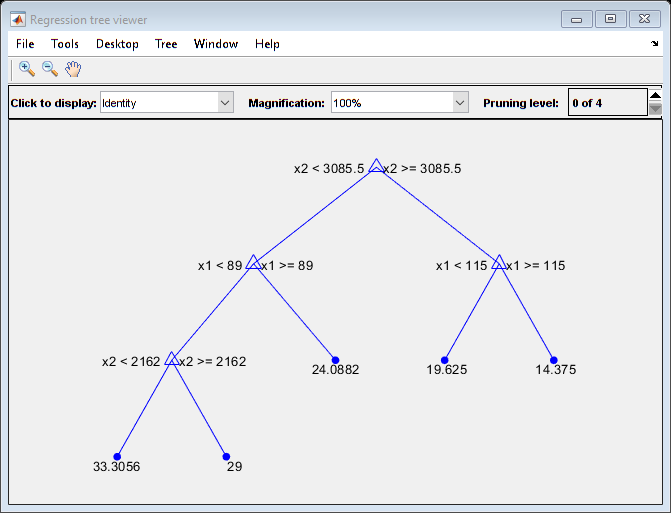

%%
view(rtree,'mode','graph') % graphic description

We have a binary tree which leads to a classification at the leaf nodes.  At non-leaf nodes, a decision (split) is made using a single feature from the dataset which can be written as an "if...then...else" rule.  So, for a test point, it's pretty easy to explain the decisions that lead the classifier to the prediction it makes.

A tree like this produces decision boundaries that partition the space into axis-aligned rectangles. From [HTF]:

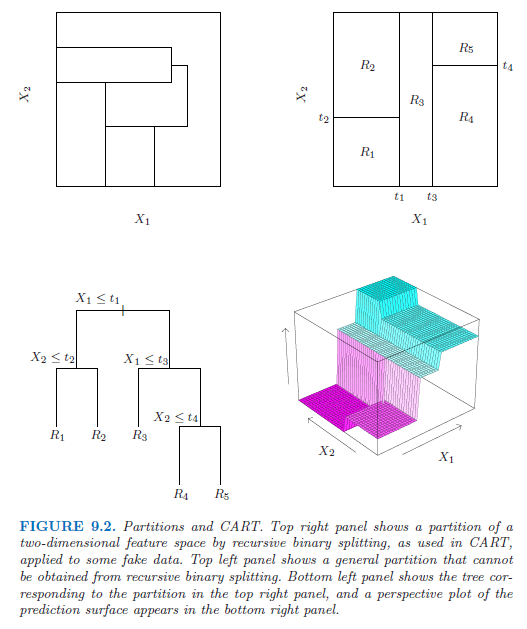

## Learning Decision Trees

Given a dataset, how is the tree constructed?

We need a measure of **impurity**.  If a node is **pure** if it assigns the same class to every data point that "comes its way" (e.g. the leaf nodes for the Iris data above).  The tree is constructed by splitting nodes to minimise impurity.  Commonly used measures of impurity:

- entropy

- Gini index

- misclassification

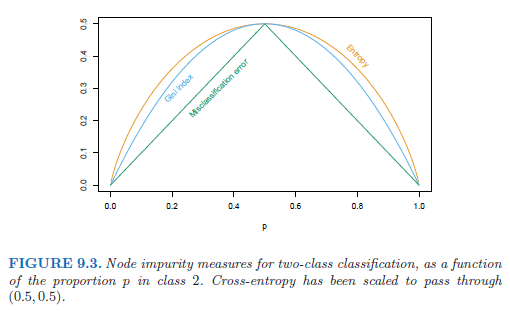

Well-known (similar) algorithms are "Classification and Regression Trees" (CART), ID3 and C4.5.

## Why Do Ensembles Work?

How can ensembles produce good generalization performance?  Instead of a single predictor, we are using a committee of many!  What about all those parameters?  What about overfitting?

Ensembles can be understood with respect to the bias-variance decomposition of error that we have used throughout the course.

Assume that the outputs of the base learners, $d_j$ are independent and identically distributed (iid).  Then:


$$E[y]=E\left[ \sum_j \frac{1}{L} d_j \right] = \frac{1}{L} L \cdot E[d_j] = E[d_j]$$



$$Var(y) = Var \left( \sum_j \frac{1}{L} d_j \right) = \frac{1}{L^2} Var \left(\sum_j d_j \left) = \frac{1}{L^2} L \cdot Var(d_j) = \frac{1}{L} Var(d_j)$$


So the bias does not chance compared to a single learner, but the variance decreases as $L$ increases.

In practice the gain is unlikely to be this good because the base learners are probably not iid.  So it's more like:


$$Var(y) = \frac{1}{L^2} Var \left(\sum_j d_j \left) = \frac{1}{L^2}\left[ 
 \sum_j Var(d_j) + 2 \sum_j \sum_{i<j} Cov(d_i,d_j) \right]$$


Clearly the number of parameters in an ensemble is probably not a good indication of model complexity. Alpaydin talks a bit about the desire to have a diverse set of learners and there are many possibilities here (e.g. sensor fusion). But success is not guaranteed!  If the base learners have low bias, then we stand to get a very good result from reducing variance.  But we want the learners to be "simple", otherwise they are likely not to be diverse.  But if they are simple, maybe they have high bias. But... :)

Also see next week for a Bayesian point of view on ensembles.

## Random Forests

Random forests (RFs) are regarded as a "state of the art" machine learning technique.

A RF is a large collection of decorrelated trees.

A RF is arguably easier to train and tune than boosting.

In a RF, trees are generated via bagging:

- Each tree is identically distributed

- Bias of many trees = bias of a single tree

- RF tries to reduce the variance.

Average of B i.i.d random variables (each with variance $\sigma^2$):


$$\frac{1}{B} \sigma^2$$


If variables are correlated (pairwise correlation $\rho$) then the variance of the average is:


$$\rho \sigma^2 + \frac{1-\rho}{B} \sigma^2$$


IDEA: reduce correlation between trees to reduce the 1st term.

- Select $m \leq d$ input variables at random as candidates for splitting.

Hyperparameters:

- Number of trees: cross-validation

- $m : \lfloor \sqrt{d} \rfloor$for classification, $\left \lfloor \frac{d}{3} \right \rfloor$for regression

RFs use an "out of bag" sample for prediction during error estimation: for data point $i$, only the trees that were trained without $i$ are used for a majority vote/average.

[HTF] has some example results with random forests and more discussion of the details.